%clear all

f = @(t, tau, G, A0) A0.*exp((G./2 - 3./2).*t ./ tau) .* ...
    cos(sqrt(-(G - 1).*(G - 5)) .* t ./ 2 ./ tau);


intervallo = [0, 2];
tau = 0.05;

figure;

### Sovrasmorzato

subplot(2, 2, 1)
fplot(@(x) f(x, tau, 0.9, 1), intervallo)
text(0.25, 0.8, "sottosmorzato (G = 0.9)")
xlabel("tempo")
ylabel("segnale")

### Smorzato 1

subplot(2, 2, 3)
fplot(@(x) f(x, tau, 1.5, 1), intervallo)
text(0.4, 0.8, "smorzato (G = 1.5)")
xlabel("tempo")
ylabel("segnale")

### Smorzato 2

subplot(2, 2, 2)
fplot(@(x) f(x, tau, 2.8, 1), intervallo)
text(0.4, 0.8, "smorzato (G = 2.8)")
xlabel("tempo")
ylabel("segnale")

### costante 2

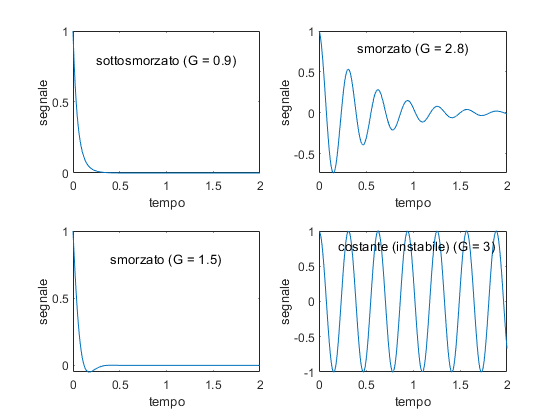

subplot(2, 2, 4)
fplot(@(x) f(x, tau, 3, 1), intervallo)
text(0.2, 0.8, "costante (instabile) (G = 3)")
xlabel("tempo")
ylabel("segnale")
saveas(gcf, "tmp/plot_1.png")

### creascente 1

figure;
subplot(2, 2, 1)
fplot(@(x) f(x, tau, 3.1, 1), intervallo)
text(0.2, 5, "creascente (G = 3.1)")
xlabel("tempo")
ylabel("segnale")

### creascente 2

subplot(2, 2, 3)
fplot(@(x) f(x, tau, 3.3, 1), intervallo)
text(0.2, 250, "creascente (G = 3.3)")


### limite

xlabel("tempo")
ylabel("segnale")
subplot(2, 2, 2)
fplot(@(x) f(x-0.13, tau, 4.5, 1e-6), intervallo)
text(0.1, 7e5, "prossimo al limite (G = 4.8)")
xlabel("tempo")
ylabel("segnale")

### oltre

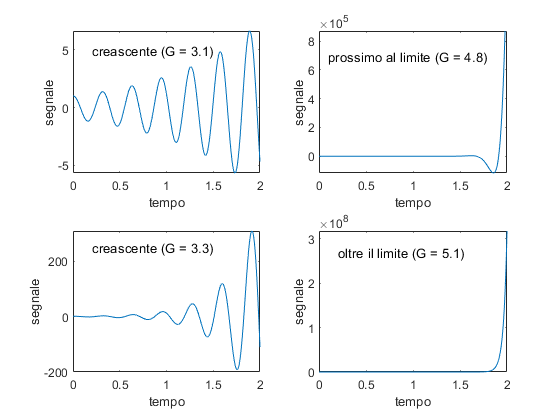

subplot(2, 2, 4)
fplot(@(x) f(x, tau, 5.1, 1e-15), intervallo)
text(0.2, 2.7e8, "oltre il limite (G = 5.1)")
xlabel("tempo")
ylabel("segnale")
saveas(gcf, "tmp/plot_2.png")

%0.9 - 2.9
%3
%3.1
%4.8
%5.1